# Denoise Speech Using Deep Learning Networks

This example shows how to denoise speech signals using convolutional neural networks, a common network type for image data. We will generate images from the signal data using [spectrograms](https://www.mathworks.com/help/signal/ref/spectrogram.html). 

The data set consists of multiple MP3 files of different people speaking a sentance.  

To train the denoiser model we will add washing machine noise to clean speech data. The speech data disturbed with noise will be the predictors, and the clean speech data will be the response. 

## Introduction

The aim of speech denoising is to remove noise from speech signals while enhancing the quality and intelligibility of speech. This example showcases the removal of washing machine noise from speech signals using a deep learning network. 

## Create Datastore

Download the dataset from [https://common-voice-data-download.s3.amazonaws.com/cv_corpus_v1.tar.gz](https://common-voice-data-download.s3.amazonaws.com/cv_corpus_v1.tar.gz) and untar the downloaded file. Set `datafolder` to the location of the data.

To do deep learning we need a quite large data set. In the folder *cv-other-train *we have 121,129 sound files in an mp3 format. To easily work with these files, we will create a datastore, which is basically a pointer towards the data. Specifically, this is an [audioDataStore](https://www.mathworks.com/help/audio/ref/audiodatastore.html) which has audio specific functionality. 

datafolder = fullfile(pwd,"cv_corpus_v1");
ads = audioDatastore(fullfile(datafolder,"cv-other-train"));

We shuffle the data, and then we choose a subset of the data to work with, which is 1000 files. To just work with 1000 files is a choise made to make the example will run faster. To get a better model, it is better to work with more data. 

ads = shuffle(ads);
ads = subset(ads,1:1000);

## Read and listen to first file

[cleanAudio,info] = read(ads); 
sound(cleanAudio,info.SampleRate)

## Sample rate converter

Since speech generally falls below 48 kHz, we will downsample the clean audio signal to 8 kHz to reduce some computational load of the network. 

inputFs      = 48e3;
Fs           = 8e3;
src = dsp.SampleRateConverter("InputSampleRate", inputFs,...
                              "OutputSampleRate", Fs,...
                              "Bandwidth", 7920);

Downsample 48kHz --> 8kHz

D     = inputFs / Fs;
L     = floor(numel(cleanAudio)/D);
cleanAudio = cleanAudio(1:D*L);
cleanAudio = src(cleanAudio);
reset(src);

## Add noise

The next thing we will do is to add washing machine noise to the speech signal. we will set the noise power so that the signal-to-noise ratio (SNR) is zero dB. A SNR of zero indicates that the desired signal is virtually indistinguishable from the unwanted noise.

noise         = audioread("WashingMachine-16-8-mono-1000secs.wav");
randind      = randi(numel(noise) - numel(cleanAudio) , [1 1]);
noiseSegment = noise(randind : randind + numel(cleanAudio) - 1);
noisePower   = sum(noiseSegment.^2);
cleanPower   = sum(cleanAudio.^2);
noiseSegment = noiseSegment .* sqrt(cleanPower/noisePower);
noisyAudio   = cleanAudio + noiseSegment;

## Listen to noisy data

sound(noisyAudio,Fs)

## Plot noisy audio and clean audio

t = (1/Fs) * ( 0:numel(cleanAudio)-1);
subplot(211)
plot(t,noisyAudio)
title("Noisy Audio")
grid on
subplot(212)
xlabel("Time (s)")
plot(t,cleanAudio)
title("Clean Audio")
grid on

## Generate network image input data

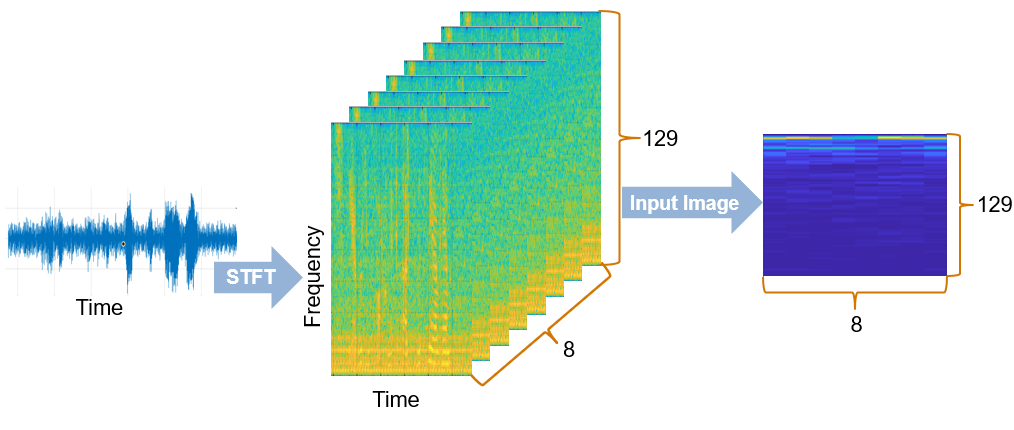

#### Steps

- We will take both the clean audio data and the noisy audio data and convert it into spectrogram images. Spectrograms are a Fourier transform on short snippets of data – also known as Short Time Fourier Transform – which outputs frequency on one axis and time on the other. 

- We take each spectrogram of the noisy audio and shift it in backwards in time so that we end up with 8 consecutive spectrograms. 

- We will then train the network using images based on these spectrograms - the time shift of 8 on one axis and the frequency resolution of 129 on the other. 

Let’s define the parameters needed to do our spectrograms. We will use a Hamming window of length 256 samples and an overlap of 75% of the window length. 

#### The parameters needed to do the spectrograms

WindowLength = 256;
win          = hamming(WindowLength,"periodic");
Overlap      = round(0.75 * WindowLength);
FFTLength    = WindowLength;
NumFeatures  = FFTLength/2 + 1;
NumSegments  = 8;

#### Step 1: Calculate the spectrograms

cleanSTFT = spectrogram(cleanAudio, win, Overlap, FFTLength, Fs); 
cleanSTFT = abs(cleanSTFT);
noisySTFT = spectrogram(noisyAudio, win, Overlap, FFTLength,Fs);
noisySTFT = abs(noisySTFT);
figure
subplot(211)
spectrogram(cleanAudio, win, Overlap, FFTLength, Fs)
subplot(212)
spectrogram(noisyAudio, win, Overlap, FFTLength,Fs)

#### Step 2: Generate 8-segment training predictor signals

We create 8 copies of the spectrogram that we shift by one spectrogram-time step for each. Now we have our Predictors and Targets. 

noisySTFT    = [noisySTFT(:,1:NumSegments-1) noisySTFT];
STFTSegments = zeros(NumFeatures, NumSegments , size(noisySTFT,2) - NumSegments + 1);
for index = 1:size(noisySTFT,2) - NumSegments + 1
    STFTSegments(:,:,index) = (noisySTFT(:,index:index+NumSegments-1)); 
end
targets    = cleanSTFT;
size(targets)
predictors = STFTSegments;
size(predictors)
figure, imagesc(STFTSegments(:,:,1))
figure, imagesc(targets(:,1))

## Work with the larger data set

Even though we created the datastore a while back, we were still just working with one file. Now, let’s start working with the 1000 files we chose to keep. To do that easily we convert the datastore into a [tall array](https://www.mathworks.com/help/matlab/tall-arrays.html). 

Tall arrays are arrays that can have more rows than what actually fits into memory. Perfect for big data sets.  When we perform a set of commands on the Tall array they will remain unevaluated until we call the gather function. This deferred evaluation enables us to work quickly with large data sets. When we eventually request output using gather, MATLAB combines the queued calculations where possible and takes the minimum number of passes through the data, which can also be performed in parallel if you have multiple cores on your computer.

reset(ads);
T = tall(ads)

## Extract target and predictor from Tall table

In this section we will do the entire procedure which we did for that one file, from reading it in to getting the target and predictors, all in one line in a helper function *HelperGenerateSpeechDenoisingFeatures*. It’s not until we run the gather command that the function is actually running. 

We can see that MATLAB has identified that we only need to do one pass of the data to be able to do the calculations in the helper function. 

[targets,predictors] = cellfun(@(x)HelperGenerateSpeechDenoisingFeatures(x,noise,src), T,"UniformOutput",false);

Call gather to actually perform the calculations. 

[targets,predictors] = gather(targets,predictors);

## Normalize and reshape the data 

It is good practice to normalize all features to zero mean and unity standard deviation.

Compute the mean and standard deviation of the predictors and targets, respectively, and use them to normalize the data.

predictors    = cat(3, predictors{:});
targets       = cat(2, targets{:});
noisyMean     = mean(predictors(:));
noisyStd      = std(predictors(:));
predictors(:) = (predictors(:)-noisyMean)/noisyStd;
cleanMean     = mean(targets(:));
cleanStd      = std(targets(:));
targets(:)    = (targets(:)-cleanMean)/cleanStd;

Reshape predictors and targets to the dimensions expected by the deep learning network.

predictors  = reshape(predictors,size(predictors,1),size(predictors,2),1,size(predictors,3));
targets     = reshape(targets,1,1,size(targets,1),size(targets,2));

## Split into Training and Validation data

You will use 1% of the data for validation during training. Validation is useful to detect scenarios where the network is overfitting the training data.

Randomly split the data into training and validation sets.

inds                = randperm(size(predictors,4));
L                   = round(0.99 * size(predictors,4));
trainPredictors     = predictors(:,:,:,inds(1:L));
trainTargets        = targets(:,:,:,inds(1:L));
validatePredictors  = predictors(:,:,:,inds(L+1:end));
validateTargets     = targets(:,:,:,inds(L+1:end));

## Speech Denoising with Convolutional Layers

Define the layers of a fully convolutional network comprising 16 convolutional layers. The first 15 convolutional layers are groups of 3 layers, repeated 5 times, with filter widths of 9, 5, and 9, and number of filters of 18, 30 and 8, respectively. The last convolutional layer has a filter width of 129 and 1 filter. In this network, convolutions are performed in only one direction (along the frequency dimension), and the filter width along the time dimension is set to 1 for all layers expect the first one. 

layers = [imageInputLayer([NumFeatures,NumSegments])
          convolution2dLayer([9 8],18,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          repmat(...
          [convolution2dLayer([5 1],30,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          convolution2dLayer([9 1],8,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          convolution2dLayer([9 1],18,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer], 4,1) % repeat this sequence 4 times
          
          convolution2dLayer([5 1],30,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          convolution2dLayer([9 1],8,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          convolution2dLayer([129 1],1,"Stride",[1 100],"Padding","same")
          
          regressionLayer
          ]

## Training options

Let's specify the training options for the network. We set `MaxEpochs` to `3` so that the network makes 3 passes through the training data. We set `MiniBatchSize` of `128` so that the network looks at 128 training signals at a time. We specify `Plots` as `"training-progress"` to generate plots that show the training progress as the number of iterations increases. We set `Verbose` to `false` to disable printing the table output that corresponds to the data shown in the plot into the command line window. We specify `Shuffle` as `"every-epoch"` to shuffle the training sequences at the beginning of each epoch. We specify `LearnRateSchedule` to `"piecewise"` to decrease the learning rate by a specified factor (0.9) every time a certain number of epochs (1) has passed. We set `ValidationData` to the validation predictors and targets. We set `ValidationFrequency` such that the validation mean square error is computed once per epoch. And we set `ValidationPatience` to `Inf` to turn off the built-in validation stopping criterion. 

This example uses the adaptive moment estimation (ADAM) solver.

options = trainingOptions("adam", ...
    "MaxEpochs",3, ...
    "InitialLearnRate",1e-5,...
    "MiniBatchSize",miniBatchSize, ...
    "Shuffle","every-epoch", ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "ValidationPatience",Inf,...
    "ValidationFrequency",floor(size(trainPredictors,4)/miniBatchSize),...
    "LearnRateSchedule","piecewise",...
    "LearnRateDropFactor",0.9,...
    "LearnRateDropPeriod",1,...
    "ValidationData",{validatePredictors,permute(validateTargets,[3 1 2 4])});miniBatchSize = 128;

## Train network

Train the network with the specified training options and layer architecture using `trainNetwork`. Because the training set is large, the training process can take several minutes. 

denoiseNetFullyConvolutional = trainNetwork(trainPredictors,permute(trainTargets,[3 1 2 4]),layers,options);

## Test the Denoising Networks

Use speech signals from the "cv-valid-test" folder to test the performance of the trained networks. Use `audioDatastore` to create a datastore for the files in the "cv-valid-test" folder.

ads = audioDatastore(fullfile(pwd,"cv_corpus_v1\cv-other-test"));
noise         = audioread("WashingMachine-16-8-mono-200secs.wav");
[denoisedAudio, cleanAudio, noisyAudio] = testNetwork(ads, noise, src, D); 

Plot the clean, noisy and denoised audio signals.

figure;
t = (1/Fs) * ( 0:numel(denoisedAudio)-1);

subplot(321)
plot(t,cleanAudio(1:numel(denoisedAudio)))
title("Clean Speech")
grid on
subplot(322)
spectrogram(cleanAudio, win, Overlap, FFTLength,Fs);
title("Clean Speech")
grid on
subplot(323)
plot(t,noisyAudio(1:numel(denoisedAudio)))
title("Noisy Speech")
grid on
subplot(324)
spectrogram(noisyAudio, win, Overlap, FFTLength,Fs);
title("Noisy Speech")
grid on
subplot(325)
plot(t,denoisedAudio)
title("Denoised Speech")
grid on
xlabel("Time (s)")
subplot(326)
spectrogram(denoisedAudio, win, Overlap, FFTLength,Fs);
title("Denoised Speech")
grid on

## Listen to the results

Noisy speech

sound(noisyAudio,Fs)

Denoised speech

sound(denoisedAudio,Fs)

Clean speech

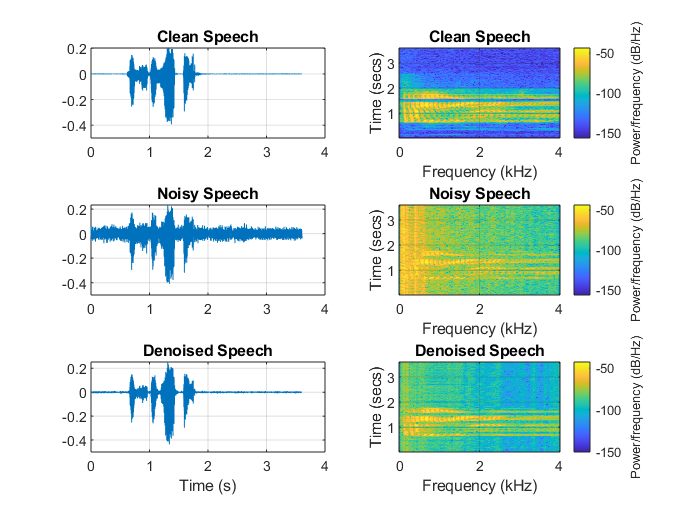

sound(cleanAudio,Fs)